clear%cleartheworkspace
R=2%definetheparameterR

R = 2

u=linspace(0,pi,100)'%laydownasetofpointsintheu-domainasacolumnvector

u =          0
    0.0317
    0.0635
    0.0952
    0.1269
    0.1587
    0.1904
    0.2221
    0.2539
    0.2856


a=0.4;
l=0.4

l = 0.4000

r=[-2*a*(cos(u)-l).*cos(u)-(1-l),2*a*(l-cos(u)).*sin(u)]%compute the position vector

r =    -1.0800         0
   -1.0794   -0.0152
   -1.0774   -0.0303
   -1.0742   -0.0453
   -1.0698   -0.0599
   -1.0640   -0.0743
   -1.0571   -0.0881
   -1.0490   -0.1014
   -1.0398   -0.1141
   -1.0295   -0.1261


drdu=diff(r)./diff(u)%compute an approximation to the derivative

drdu =     0.0203   -0.4795
    0.0608   -0.4766
    0.1010   -0.4708
    0.1408   -0.4622
    0.1798   -0.4507
    0.2180   -0.4365
    0.2552   -0.4196
    0.2911   -0.4000
    0.3256   -0.3779
    0.3586   -0.3533


That=drdu./sqrt(sum(drdu.^2,2))%compute the unit tangent vector

That =     0.0423   -0.9991
    0.1266   -0.9920
    0.2098   -0.9777
    0.2913   -0.9566
    0.3705   -0.9288
    0.4468   -0.8946
    0.5196   -0.8544
    0.5884   -0.8086
    0.6528   -0.7575
    0.7123   -0.7018


x_ri=That(:,1)

x_ri =     0.0423
    0.1266
    0.2098
    0.2913
    0.3705
    0.4468
    0.5196
    0.5884
    0.6528
    0.7123


y_ri=That(:,2)

y_ri =    -0.9991
   -0.9920
   -0.9777
   -0.9566
   -0.9288
   -0.8946
   -0.8544
   -0.8086
   -0.7575
   -0.7018


deltangle=rad2deg(acos(dot(x_ri,y_ri)))

deltangle = 0.0000 + 68.5909i


N=diff(That)./diff(u(1:end-1))%compute the normal vector

N =     2.6551    0.2252
    2.6228    0.4478
    2.5695    0.6656
    2.4961    0.8762
    2.4038    1.0775
    2.2940    1.2675
    2.1683    1.4447
    2.0286    1.6077
    1.8766    1.7554
    1.7144    1.8870


o =     2.6551    0.2252         0


p =     0.0423   -0.9991         0


angle =          0         0   -2.6622



Nhat=N./sqrt(sum(N.^2,2))%make it a unitnormal

Nhat =     0.9964    0.0845
    0.9857    0.1683
    0.9680    0.2508
    0.9436    0.3312
    0.9125    0.4090
    0.8753    0.4836
    0.8322    0.5545
    0.7837    0.6211
    0.7303    0.6831
    0.6724    0.7401


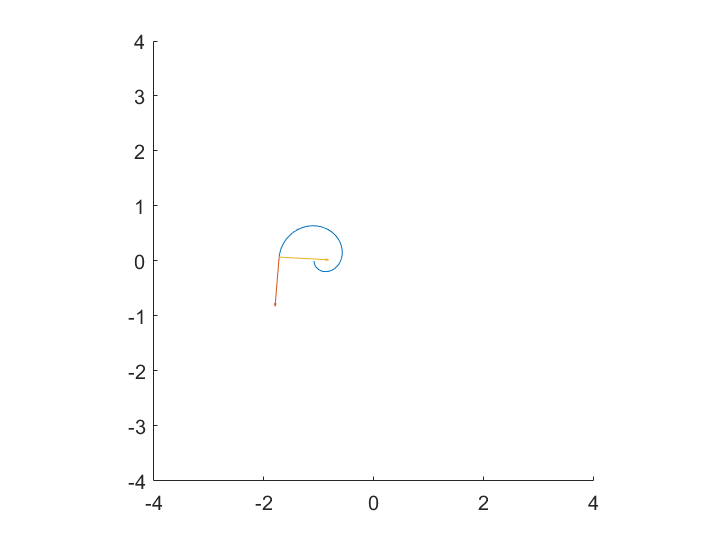

for i=1:length(u)-2%animatetheunittangentvectorandunitnormalvector
clf
hold on
plot(r(:,1),r(:,2))%plottheentirepath
quiver(r(i,1),r(i,2),That(i,1),That(i,2))%plotThat
quiver(r(i,1),r(i,2),Nhat(i,1),Nhat(i,2))%plotNhat
axis equal%equalaxissothatitlookslikeacircle
axis([-4 4 -4 4])%plotdomainlargeenoughtoseewhatisgoingon
drawnow%forcetheplottingotherwiseitwillploteverythingatonce
end